## 1. 양산 구동모터 현황

### Vehicle Modeling - Longitudinal Vehicle Dynamics

 (Eq : MotorCAD, VarName : Emlab vehicle, refcheck: Postech Nam Textbook)

https://www.caranddriver.com/lucid-motors/air

Data Import

                                         
kph = data_read(:, 1);

vehicleVarible=McadCycleParameters_MotorLAB;
mcad= actxserver('motorcad.appautomation');
vehicleVarible=getMcadVariable(vehicleVarible,mcad);


#### Rolling Resistance:


$$F_R=k_r m g \cos \theta$$


$k_r
$ :Rolloing Resistance Coefficient (0.009~0.015) 


kr=0.0054                                  % Rolloing Resistance Coefficient 
cr = kr;                                   
fr = cr;
%MotorCAD
vehicleVarible.K_r_MotorLAB;

$m$ : Mass [kg]

%
cvw = 2000;                                % 공차중량 [kg] curb vehicle weight
load = 500;                                % 부하무게 [kg]
person = 75;                               % 1인당 몸무게 [kg] Passanger Weight
no_person = 1;                             % 탑승인원 [명]
gvw = cvw+load+(person*no_person);         % 차량 총중량 [kg] 

%MotorCad
vehicleVarible.Mass_MotorLAB


$g $ : acceleration due to gravity $[m/s^2]$

ga= 9.81 ; % m/s2
for t = 0 : dif_grade : max_grade
    
    grade_tan = atan(t/100)*180/pi;
    
    Fr=kr*gvw*ga*cos(grade_tan*pi/180)
    rol_resis=cr*gvw*ga*cos(grade_tan*pi/180);

end

#### Aerodynamic Resistance:

움직이는 차량의 속도에 역풍이 불면 차량에 가해지는 공기역학적 항력은 다음과 같다.


$$F_D=\frac{1}{2} \rho\left(v+v_0\right)^2 C_d A_f$$


$\rho
$   : Air Density

$v$   : velocity of vehicle

$v_0$  : head wind velocity

$C_d$ : vehicle drag coefficeint

$A_f
$: Frontal Areal [$m^2$]

da = 1.253;                                % 공기밀도 [kg/m2]? [kg/m3]
da = 1.225;     % @ 15C and 101.32kPa [kg/m3]
vehicleVarible.rho_MotorLAB

ca = 0.3;                                  % Air Drag Coefficient 0.2< <0.4 passenger, 0.4 for sports
fa = 3.42;                                 % Frontal Area [m2]
                                          % 79~84% of width and height 

vehicleVarible.C_d_MotorLAB                                          
vehicleVarible.A_f_MotorLAB

aero_load = 0.5*da*ca*fa*(kph*1000/3600).^2;



#### Climbing Force:


$$F_c=m g \sin \theta$$


total force required for constant vehicle motion 


$$T_{\text {motor }}=\frac{\left(F_a+F_T\right) \cdot r_w}{n_d}+T_{\text {inertia }}$$


Generating Torque Ratio

Drag Coefficeint

Gear Ratio

Max Torque

Acceleration


$$F_a=m \cdot a . \delta$$


$\alpha$ : Mass Correction Factor


vehicleVarible.N_d_MotorLAB
vehicleVarible.M_o_MotorLAB


#### Angular Acceleration


$$T_{\text {inertia }}=\alpha_r\left(I_{\text {rotor }}+I_{\text {shaft }}+\frac{I_{\text {wheels }}}{n_d}\right)$$


$a_r 
$ : Angular acceleration 

$I_{rotor}$    : Inertia of rotor

$I_{shaft}$    : Inertia of shaft

$I_{wheels}$  : Inertia of Wheels


$$T_{\text {motor }}=\frac{\left(F_a+F_T\right) \cdot r_w}{n_d}+T_{\text {inertia }}$$


$r_w$ :Wheel Radius

$n_d$ : Wheel Inertia

vehicleVarible.R_w_MotorLAB
vehicleVarible.Wheellnertia

Motoring Torque Ratio

Max Speed

최대속도는 일반적으로 이 공기역학적 항력과 추력으로 정해진다. 식13.5

### Reference Vehicle Model

#### ID4

[https://en.wikipedia.org/wiki/Volkswagen_ID.4](https://en.wikipedia.org/wiki/Volkswagen_ID.4)

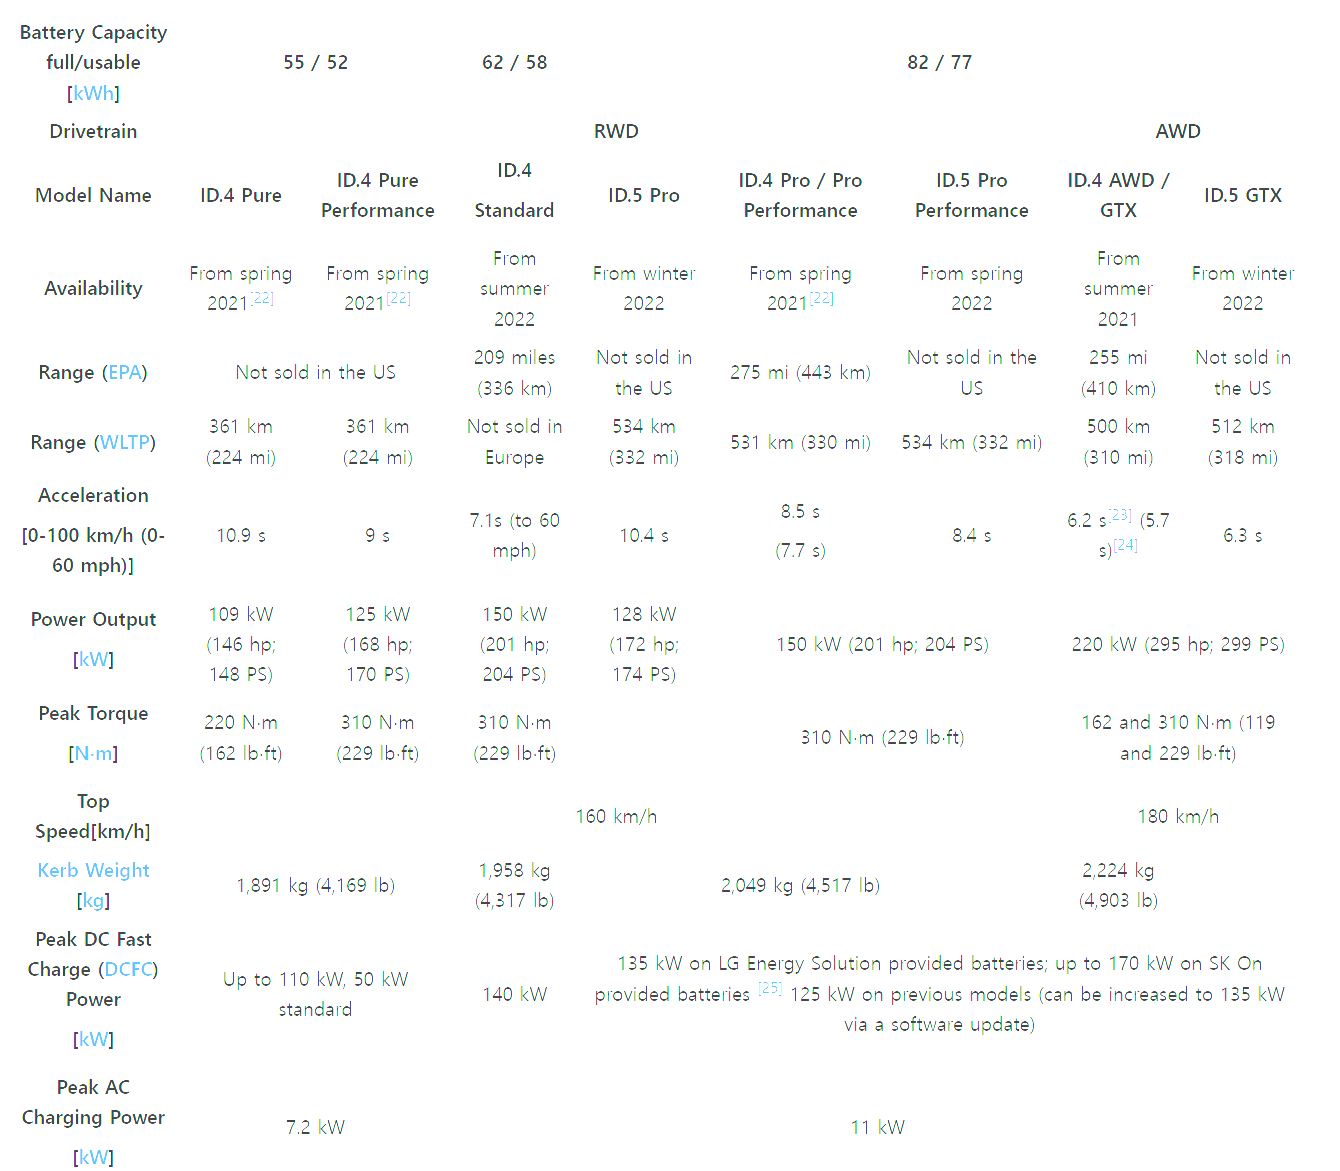

#### Tesla Model3

[https://en.wikipedia.org/wiki/Tesla_Model_3](https://en.wikipedia.org/wiki/Tesla_Model_3)

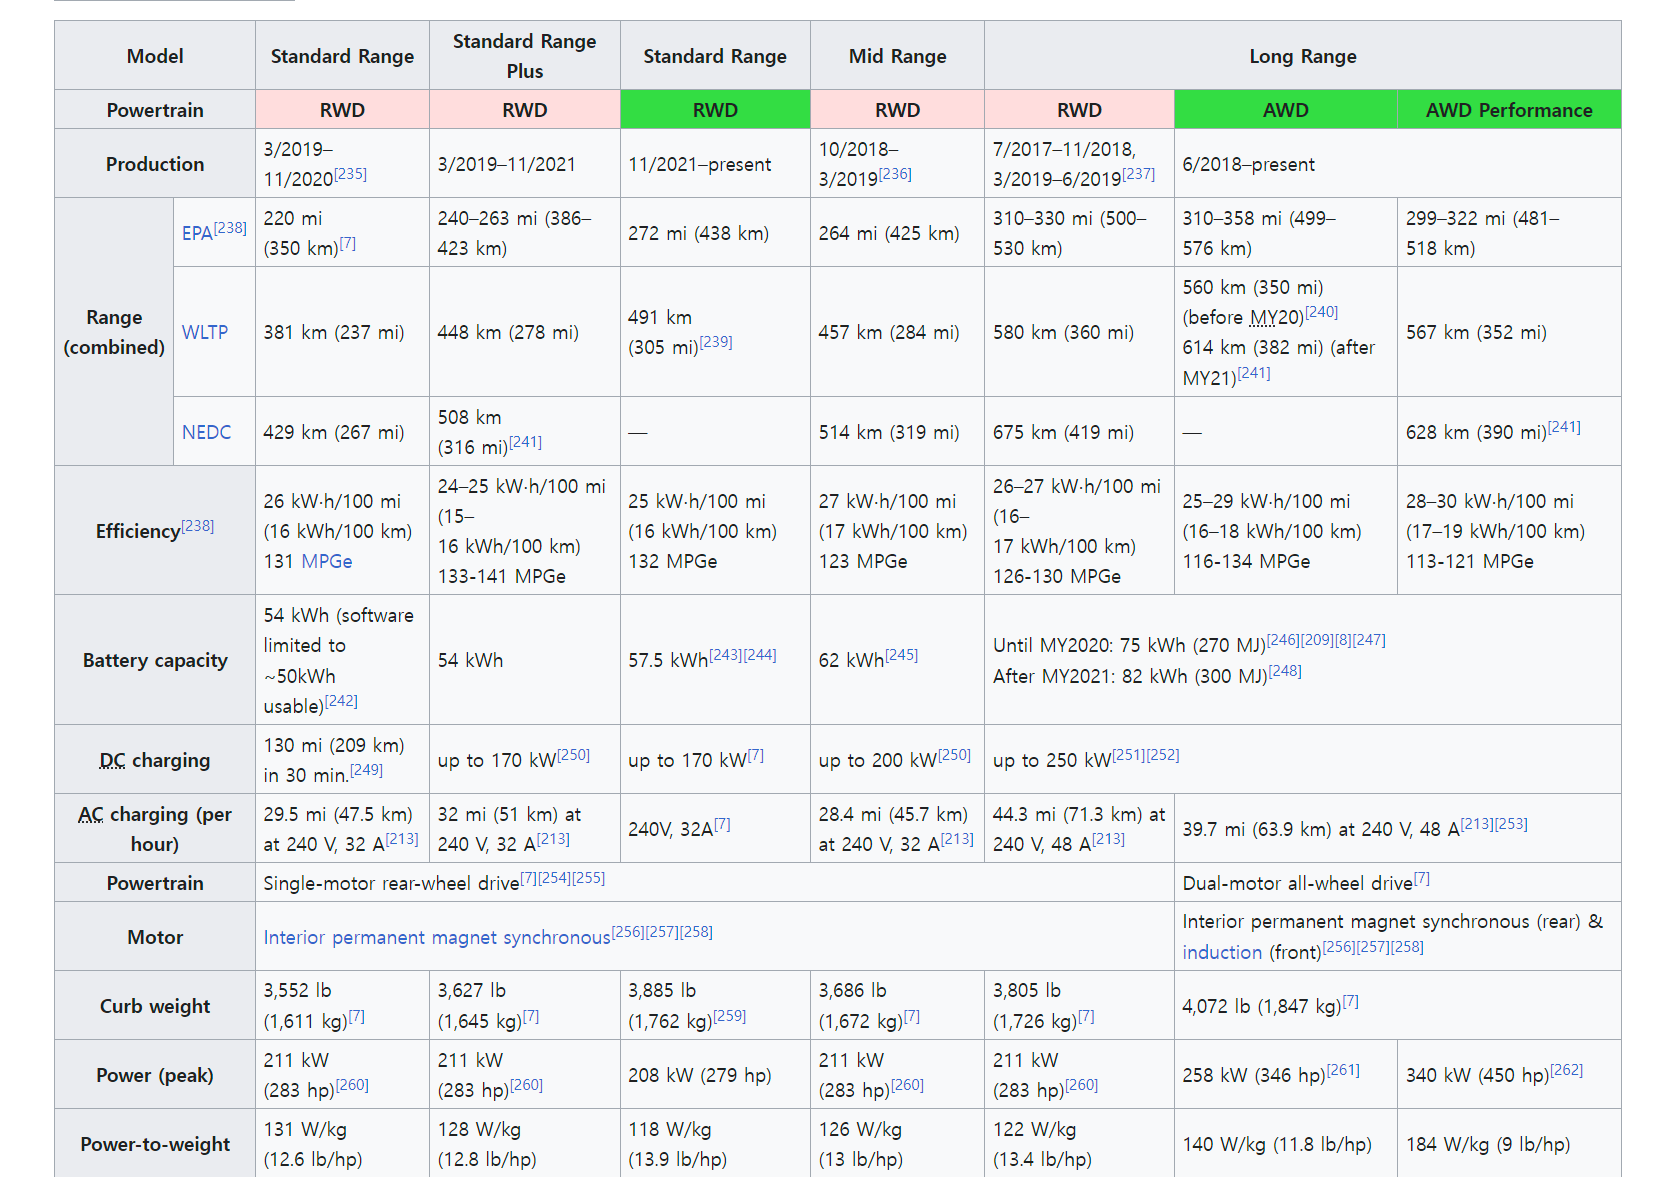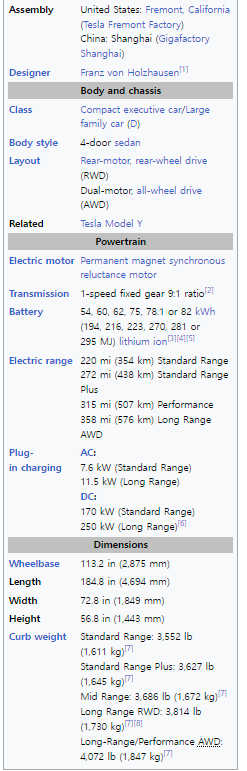

https://www.mountainpassperformance.com/motor-control-101/

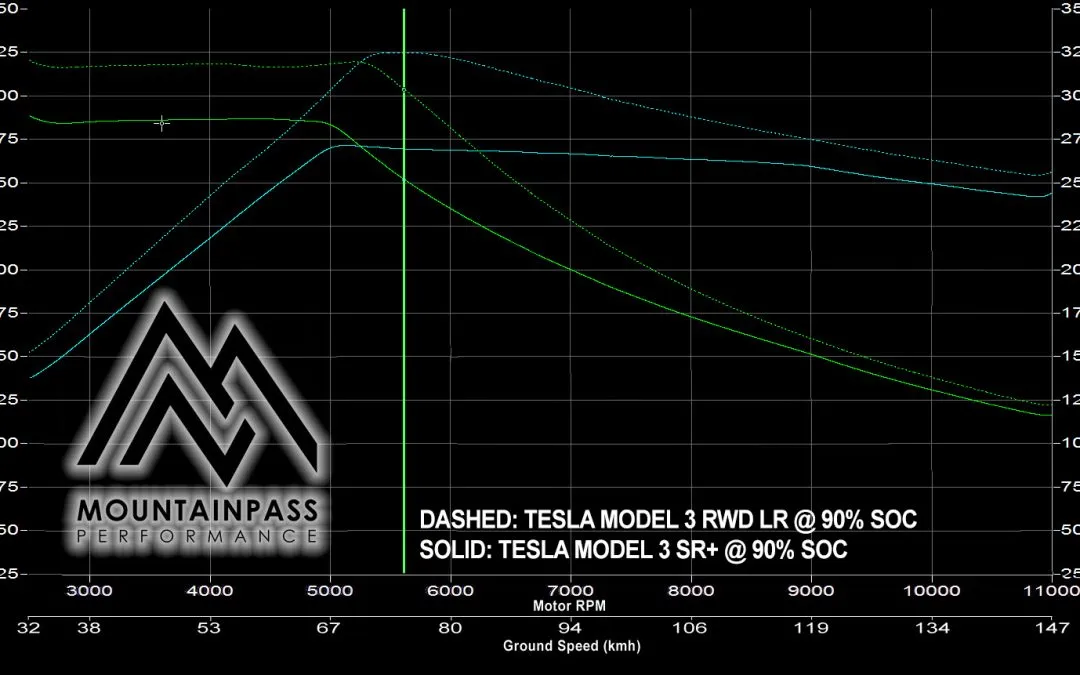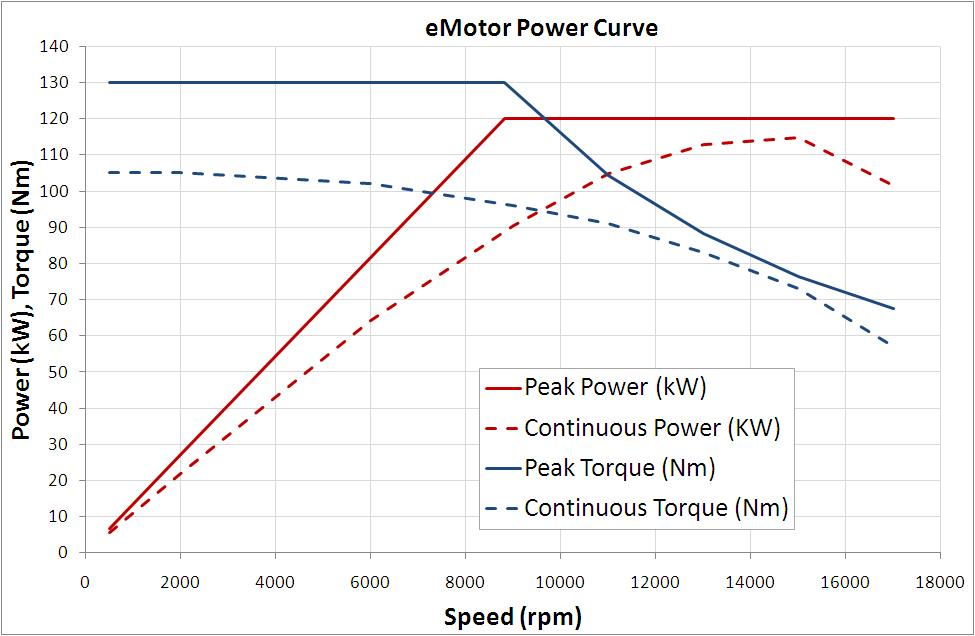

#### Lucid Air

[https://en.wikipedia.org/wiki/Lucid_Air](https://en.wikipedia.org/wiki/Lucid_Air)

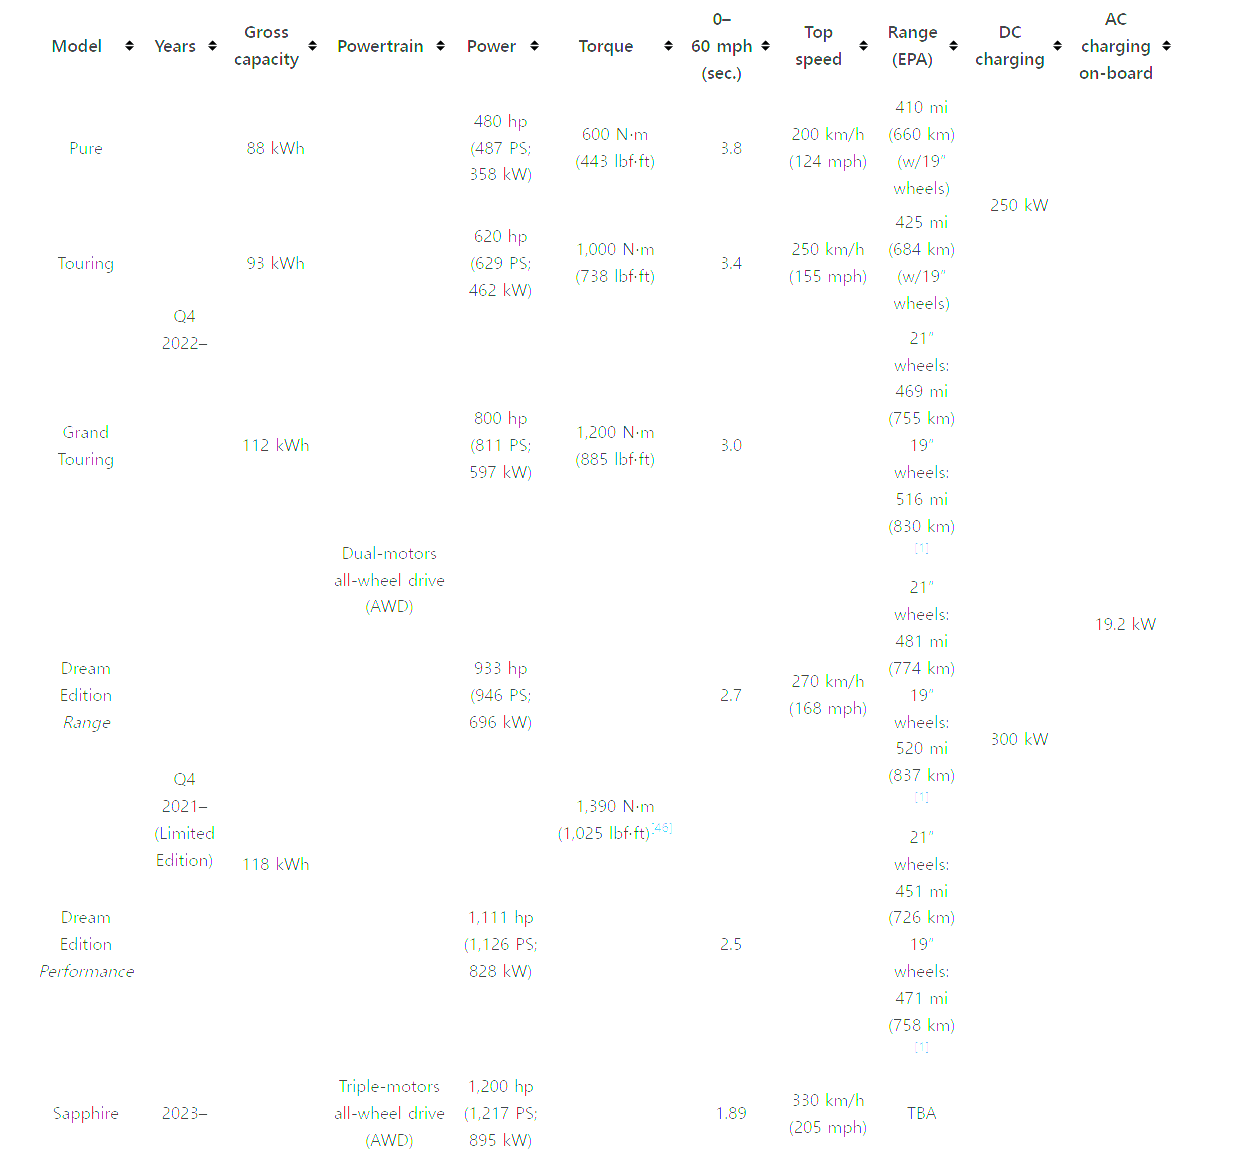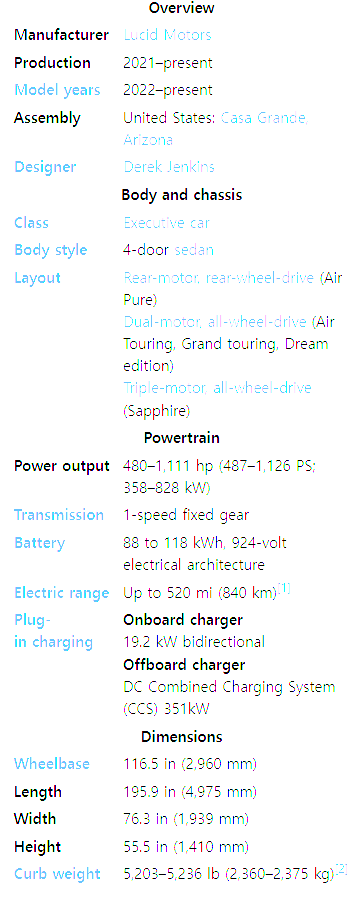

https://www.thedrive.com/news/lucids-new-469-hp-electric-motor-weighs-just-70-pounds

#### Ioniq5 

#### 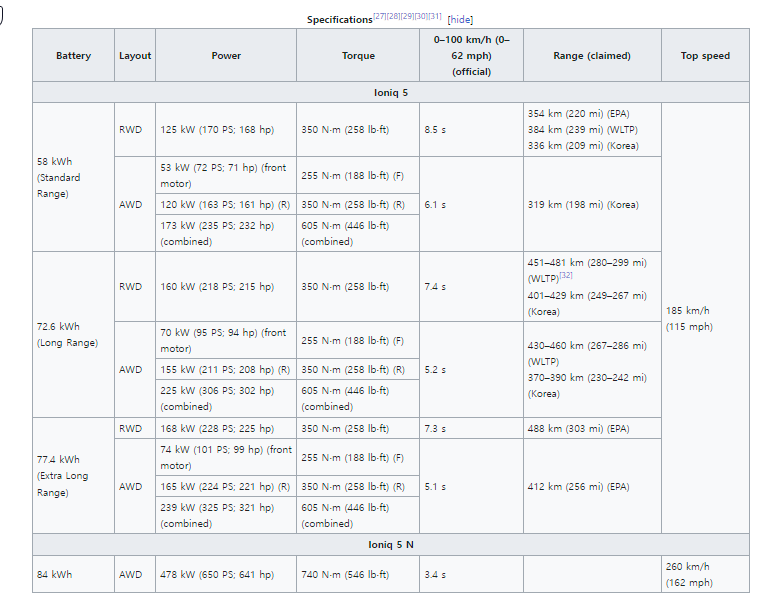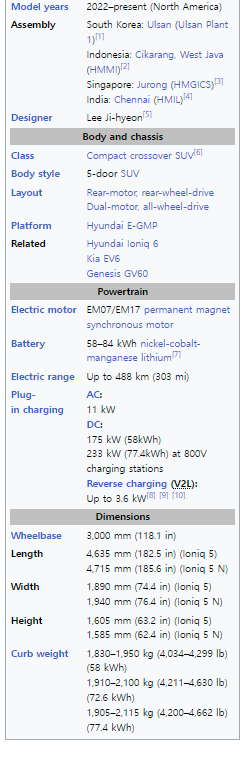

#### Tesla Model S Plaid specs:

- 19" wheels: up to 396 miles (637 km) of EPA est. range; 637 km (396 miles) WLTP21" wheels: up to 348 miles (560 km) of EPA est. range; 628 km (390 miles) WLTP; [300 miles (483 km) in IEVs 70 mph test](https://insideevs.com/reviews/543687/tesla-model-s-range-test/)

- battery capacity ([see the pack here](https://insideevs.com/news/540380/tesla-models-plaid-battery-open/)): N/A (about 99 kWh and roughly 95 kWh usable)7,920 lithium-ion 1865-type cylindrical cells (Panasonic)5 modules (1,584 cells each)22S72P (22 rows in series, each of 72 cells in parallel)about 450 V system (indicatory value)

- 0-60 mph (96.5 km/h) in 1.99 seconds (*with rollout subtracted)0-100 km/h (62 mph) in 2.1 seconds (*with rollout subtracted)[*MotorTrend*'s 0-60 mph (asphalt, no rollout): 2.28 seconds](https://insideevs.com/news/514979/tesla-cant-60mph-under-2seconds/)

- 1/4 mile 9.23 seconds at 155 mph trap speed according to Tesla website[Tesla's professional test driver record: 9.234 seconds at 152.16 mph trap speed](https://insideevs.com/news/546517/jay-leno-garage-plaid-record/)[Jay Leno's 1/4 mile record of 9.247 seconds at 152.09 mph trap speed](https://insideevs.com/news/513651/jay-leno-tesla-plaid-record/)[DragTimes' run: 9.248 seconds at 151.83 mph](https://insideevs.com/news/519291/tesla-plaid-full-performance-tests/)moddified cars:[8.994 seconds at 155 mph trap speed at Maryland International Raceway (November 2021)](https://insideevs.com/news/546552/modified-tesla-plaid-sub-9sec/)[9.081 seconds at 154.10 mph trap speed - July 24, 2021 at the World Wide Technology Raceway in St. Louis](https://insideevs.com/news/522426/tesla-models-plaid-drag-record/)

- [Nürburgring Nordschleife record of 7 minutes and 35.579 seconds (September 9, 2021)](https://insideevs.com/news/532116/tesla-models-plaid-record-nurburgring/)

- top speed:initially: 163 mph (262 km/h)in the [Plaid Track Mode](https://insideevs.com/news/559353/tesla-plaid-track-mode/): [170-175 mph (274-282 km/h)](https://insideevs.com/news/561034/tesla-models-plaid-accelerates-171mph/)advertised: 200 mph (322 km/h) †when equipped with the proper wheels and tires (initially expected in "fall 2021")

- three-motor all-wheel drive ([one motor in the front](https://insideevs.com/news/543145/tesla-plaid-front-drive-unit/) and [two motors in the rear](https://insideevs.com/news/540692/tesla-plaid-drive-rear-unit/))Permanent Magnet - Synchronous Reluctance Motors - PMSRM, all with carbon-sleeved rotor

- system output: 1,020 hp (about 760 kW)

- DC fast charging: at up to 250 kW (Superchargers)can replenish 187 miles (301 km) in 15 minutes

- Drag Coefficient 0.208 Cd

- Wheels 19" or 21"

- Cargo 28 cu ft

- Weight 4,766 lbs (2,162 kg)

https://www.youtube.com/watch?v=QnmVTlaRTLk&list=PLwPiVR1Wtwc1k_cpX76qbWW6R0UscCxCG

- 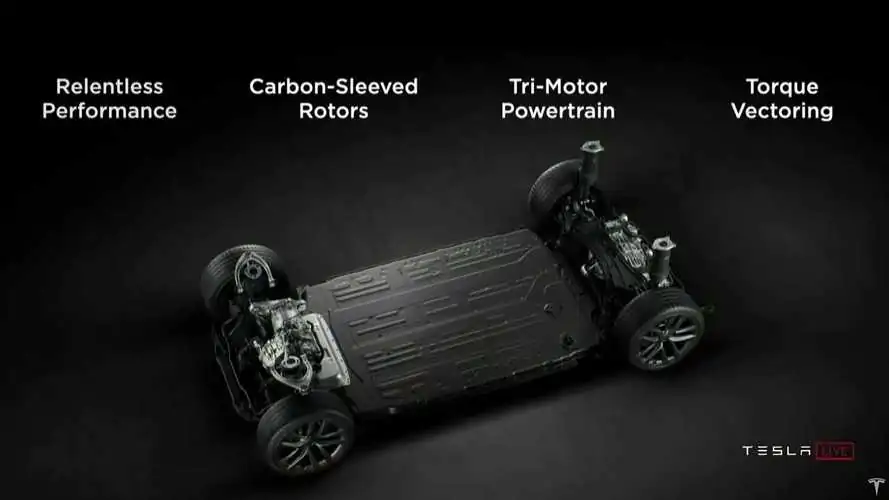

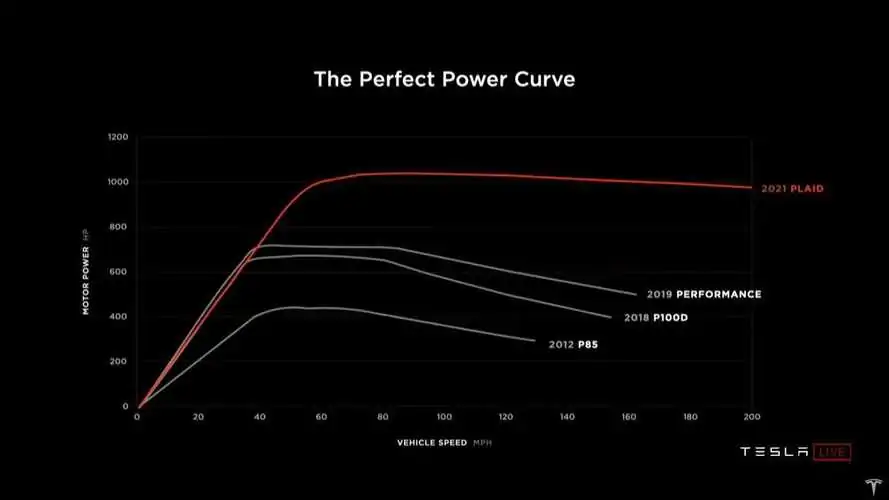

[https://www.tesla.com/ownersmanual/models/en_us/GUID-E414862C-CFA1-4A0B-9548-BE21C32CAA58.html](https://www.tesla.com/ownersmanual/models/en_us/GUID-E414862C-CFA1-4A0B-9548-BE21C32CAA58.html)

TeslaPlaidCurve


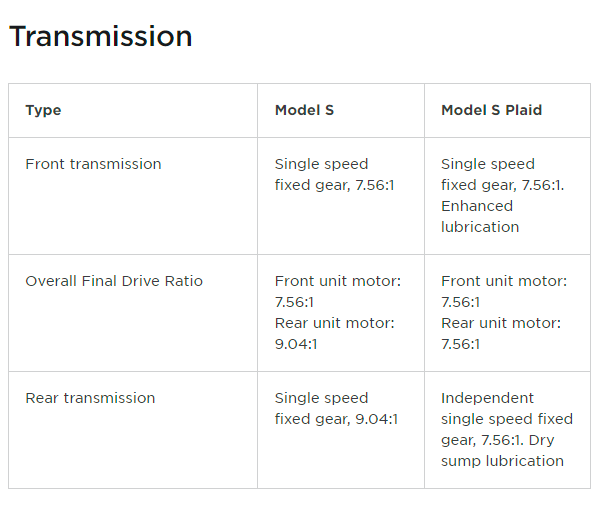

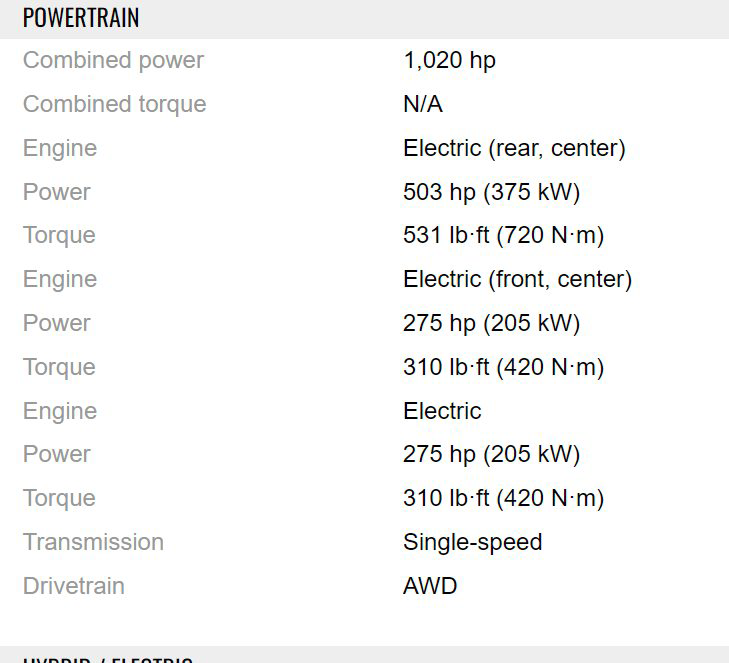

[https://mobile.guideautoweb.com/en/specifications/tesla/model-s/plaid/2022/](https://mobile.guideautoweb.com/en/specifications/tesla/model-s/plaid/2022/)

[https://www.teslarati.com/tesla-model-s-plaid-coc-europe-186mph-top-speed-images/](https://www.teslarati.com/tesla-model-s-plaid-coc-europe-186mph-top-speed-images/)

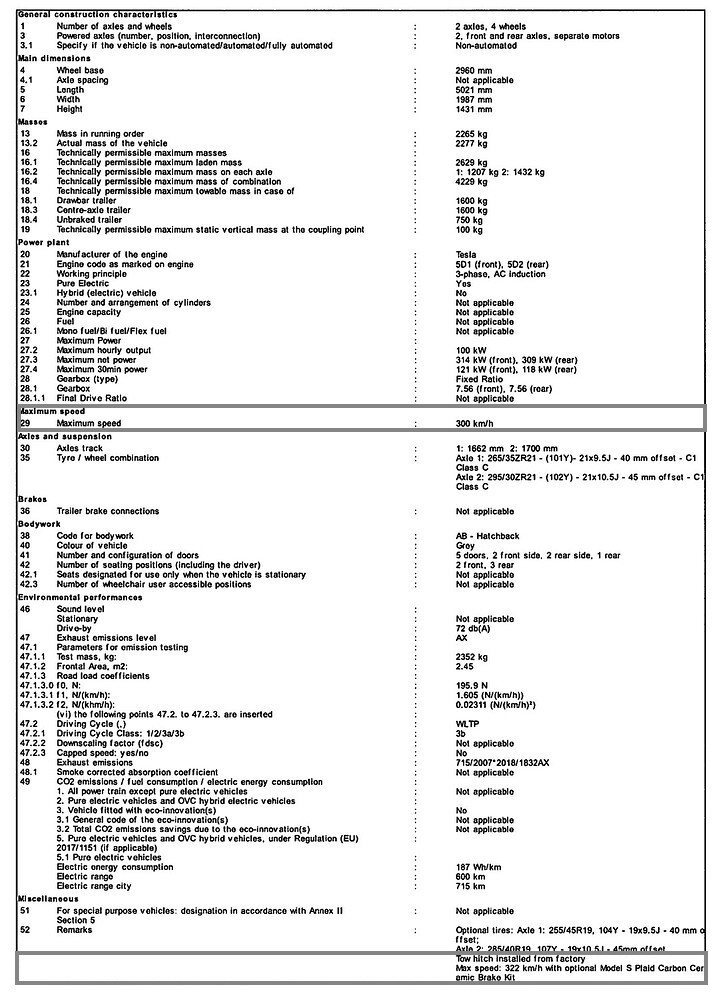

load("TeslaSPlaid.mat")
TeslaPlaidCurve

for gearRatio=7:7
    TeslaPlaid.N_d_MotorLAB=gearRatio;
    calcVehicleLateralDynamics(TeslaPlaid,vehiclePerformData);
end

%% 모터 커브 환산 이상한거같은데?

## 2. Traction Motor Spec 선정

답정너 250kW (JG)  SOD 219

## 3. 설계 도면 